clear
clc
close all

# Torque Deflection

defl_torque = readtable("defl_torque.csv"); 
% time = table2array(readtable("new_cam_time.csv"));

ang_err_filt = defl_torque{:, 1} .* pi ./ 180;
torque_sp = defl_torque{:, 2};
P = polyfit(ang_err_filt, torque_sp, 1); 
K_lin = P(1); 
offset = P(2);
% figure; 
% hold on
% 
% plot(ang_err_filt, torque_sp, ...
%     LineWidth=2)
% plot(ang_err_filt, K_lin .* ang_err_filt + offset, ...
%     LineWidth=2)
% 
% hold off

TR_post_spring = 1; 

# Fit

% Flat Region Backlash Compensation
obj_func = @(params,ang_err) sum(abs(torque_sp - params(4) - calcTorque(params(1:2),ang_err - params(3))));
params_0 = [50; 0.01; 0; 0];
Aeq = [0 1];
beq = 0;

% [params_star,fval] = fmincon(@(params)obj_func(params,ang_err_meas),params_0,[],[],Aeq,beq);
[params_star,fval] = fmincon(@(params)obj_func(params,ang_err_filt),params_0,[],[],[],[]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


K = params_star(1); % stiffness
h = params_star(2); % half the backlash
x0_val = params_star(3); % stiffness
y0_val = params_star(4); % half the backlash
tau_est = calcTorque(params_star,ang_err_filt);
tau_residuals = torque_sp - tau_est;
rms_tau = sqrt(sum(tau_residuals.^2)/length(tau_residuals)) % Nm

rms_tau = 0.5377


% Smooth Backlash Compensation
obj_func_smooth = @(L,ang_err,K,h, x0, y0) sum(abs(torque_sp - y0 - calcTorqueSmooth(L,ang_err - x0,K,h)));
L_0 = h/2;
[L_star,fval] = fmincon(@(L)obj_func_smooth(L,ang_err_filt,K,h, x0_val, y0_val),L_0,[],[],[],[]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

[tau_est_smooth,c] = calcTorqueSmooth(L_star,ang_err_filt,K,h);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


tau_smooth_residuals = torque_sp - tau_est_smooth;
% rms_tau_meas = rmse(tau_meas,torque_sp) % Nm
rms_tau_smooth = sqrt(sum(tau_smooth_residuals.^2)/length(tau_smooth_residuals)) % Nm

rms_tau_smooth = 0.5361

model_params = [K 2*h L_star c] % [Stiffness Backlash LogitBuffer LogitParam]

model_params =    53.3078    0.0232    0.0074   22.5758


# Plot

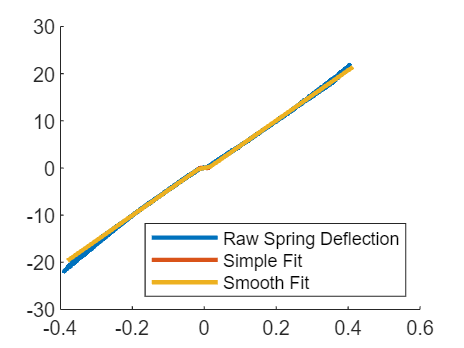

figure; 
hold on

plot(ang_err_filt - x0_val, torque_sp - y0_val, ...
    LineWidth=2, DisplayName="Raw Spring Deflection")
% plot(ang_err_filt, K_lin .* ang_err_filt, ...
    % LineWidth=2, DisplayName="linear fit")
plot(ang_err_filt,(tau_est)*TR_post_spring,...
    LineWidth=2, DisplayName="Simple Fit")
plot(ang_err_filt,(tau_est_smooth)*TR_post_spring,...
    LineWidth=2, DisplayName="Smooth Fit")
hold off
legend(Location="southeast")


writematrix([x0_val, y0_val], "Shift.csv");
writematrix(model_params, "Logit_Model_Params.csv");

# Functions

## CalcTorque

function tau = calcTorque(params,ang_err)
    K = params(1);
    h = params(2); % half the backlash
    defl = (ang_err>0).*(ang_err - h) + (ang_err<=0).*(ang_err + h);
    defl(abs(ang_err) < h) = 0;
    tau = K*defl;
end

## CalcTorqueSmooth

function [tau,c,defl] = calcTorqueSmooth(L,ang_err,K,h)
    % set up logit function
    c_0 = 30;
    c_obj_func = @(c,h,L) abs((1/(4*c) - c*(h+L)^2)*log((1/2 + c*(h+L))/(1/2 - c*(h+L))) - L);
    c = fmincon(@(c)c_obj_func(c,h,L),c_0,[],[],[],[]);
    b = 1/4/c - c*(h+L)^2;
    y_logit = @(x) b*log((0.5 + c*x)./(0.5 - c*x));

    defl = (ang_err>0).*(ang_err - h) + (ang_err<=0).*(ang_err + h);
    defl((abs(ang_err) < (h+L))) = 0;
    defl = defl + ((abs(ang_err) < (h+L))).*y_logit(ang_err);
    tau = K*defl;
end